**流域形状指数（BS）**

受构造活动干扰较强烈的地区，其河流、水系的形状多为线状或接近线状；反之，在地质构造活动性弱的地区或是受到侧向侵蚀的影响时河道演化会逐渐转变趋于圆形。BS表示河流源头至出水口的平距与垂直于该流域最大宽度的比值，计算公式为：


$$\textrm{BS}=\frac{\;B_I }{\;B_W }$$


式中，$B_I$ 代表河流源头至出水口之间的平距，$B_W$ 表示与$B_I$ 垂直方向的最大宽度。构造活动性与 $\textrm{BS}$ 值成正相关性，在同一区域，相对构造活动较强的流域显示出较高的BS值；相反，在相对构造活动较弱的区域，其BS值则偏低。BS值可划分为 3 个等级，分级标准见表3。

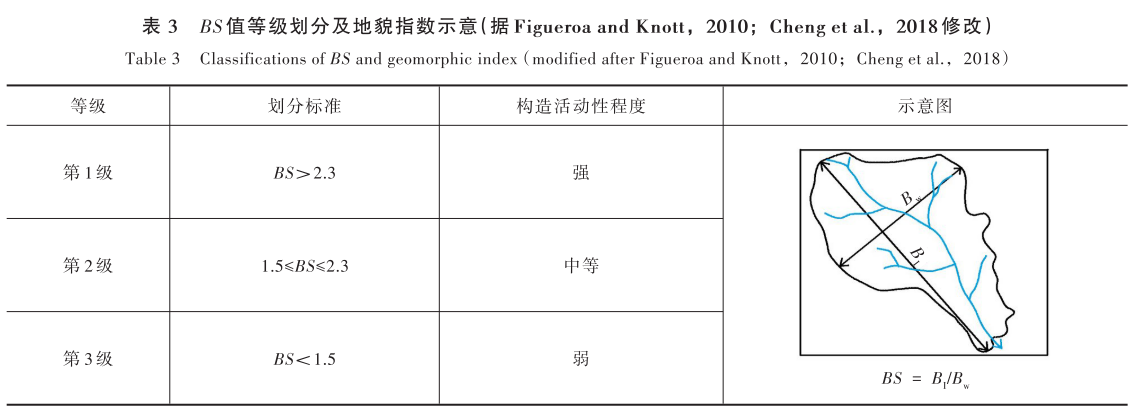

function BS_index = ttb_calculate_bs_index(dem, main_stream, show)
    [main_stream_x, main_stream_y] = STREAMobj2XY(main_stream);
    % 提取流域多边形
    basin = drainagebasins(FLOWobj(dem));
    basin_poly = GRIDobj2polygon(basin);
    boundary_points = [basin_poly.X, basin_poly.Y];

    % 获取入水口和出水口坐标
    source_point = [main_stream_x(1), main_stream_y(1)];
    pour_point = [main_stream_x(end-1), main_stream_y(end-1)];

    % 方向向量，由出水口点指向源头点
    direction_vector = source_point - pour_point;
    
    % 计算 B_I
    B_I = norm(direction_vector);

    % 构造旋转矩阵，将方向向量旋转到垂直向上
    % atan2函数返回的是从轴正方向逆时针旋转到向量所经过的弧度
    angle = pi / 2 - atan2(direction_vector(2), direction_vector(1));
    % 整体流域逆时针旋转 pi / 2 - θ 
    rotation_matrix = [cos(angle), -sin(angle); sin(angle), cos(angle)];

    % 对流域进行旋转变换，此时方向单位向量垂直
    rotated_points = (rotation_matrix * boundary_points')';

    % 两个 figure 主要用于验证旋转是否正确 √
    if show
        rotated_main_stream = (rotation_matrix * [main_stream_x, main_stream_y]')';
        figure;
        plot(boundary_points(:, 1), boundary_points(:, 2));
        hold on;
        axis equal;
        plot([pour_point(1), source_point(1)], [pour_point(2), source_point(2)]);
        plot(main_stream_x, main_stream_y);
        hold off;
        figure;
        plot(rotated_points(:, 1), rotated_points(:, 2));
        hold on;
        axis equal;
        plot(rotated_main_stream(:, 1), rotated_main_stream(:, 2));
        plot([rotated_main_stream(1, 1), rotated_main_stream(end-1, 1)], [rotated_main_stream(1, 2), rotated_main_stream(end-1, 2)]);
        hold off;

    end
    
    % 计算 B_W
    B_W = max(rotated_points(:, 1)) - min(rotated_points(:, 1));

    % 计算 BS 值
    BS_index = B_I / B_W;
end